# Rotated Copula

for dealing with negative dependencies.

add folder path that contains all function for fitting copula.

addpath('scr')

## Get data

clear;clc
load stocks

For example, get data as follows.

X1 = 5-stocks(:,1);
X2 = stocks(:,2);

`X1` and `X2` have a negative correlation

corr(X1,X2)

ans = -0.7228

## Fit Marginal Distribution

Instantly, `fitter2` fit all distribution parameter (GEV, GAM, LN, WB) and select the fittest distribution according to Anderson-Darling statistics.

F1 = fitter2(X1);

ans = 4×4 table
    DistName    ADstat      pval           keputusan      
    ________    _______    _______    ____________________

    'GEV'       0.34292    0.90256    "fails to reject h0"
    'GAM'       0.34748    0.89847    "fails to reject h0"
    'LN'        0.57686    0.66971    "fails to reject h0"
    'WB'        0.70449     0.5547    "fails to reject h0"


Meanwhile, if the data contains negative value, `fitter2` only fit the distribution with real domain (GEV).

F2 = fitter2(X2);

       - The program will only display the results
         of fitting on distributions with real domains.


ans = 1×4 table
    DistName    ADstat      pval           keputusan      
    ________    _______    _______    ____________________

    GEV         0.18004    0.99493    "fails to reject h0"


Moreover, if your data is discrete, `fitter2` fit the data with negative binomial distribution.

## Fit copula

After transforming the data according to the fittest marginal distribution, the fittest copula function is selected using `mycopulaCvM`. 

u1 = cdf(F1,X1);
u2 = cdf(F2,X2);
Cop = mycopulaCvM([u1,u2]);

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: -34.112316 



first_five = 5×7 table
      famili       param1      param2        CvM       pValue       RMSE        AIC  
    ___________    _______    _________    ________    _______    ________    _______

    'BB8-90'       -5.3383    [-0.7318]    0.039715    0.65539    0.019929     -66.65
    'Frank-270'    -6.0224    []           0.062238    0.57177    0.024948    -66.239
    'Frank'        -6.0224    []           0.062238    0.57177    0.024948    -66.239
    'Frank-90'     -6.0224    []           0.062238    0.57177    0.024948    -66.239
    'Frank-180'    -6.0224    []           0.062238    0.57177    0.024948    -66.239


You got the 90 degrees rotated BB8 as your copula. 

mycop = Cop(1)

mycop = struct with fields:
    famili: 'BB8-90'
    param1: -5.3383
    param2: -0.7318
       CvM: 0.0397
    pValue: 0.6554
      RMSE: 0.0199
       AIC: -66.6504


You can plot the joint CDFs and joint PDFs as previous example.

## Joint PDFs

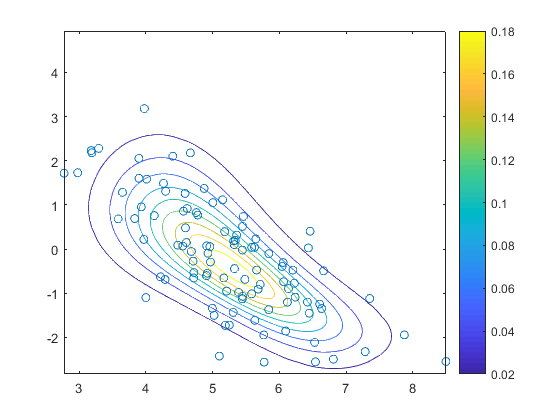

x1 = 0:0.01:1;
y1 = 0:0.01:1;
[u1,v1] = meshgrid(x1,y1);
cx = pdfcopula(mycop.famili,[u1(:),v1(:)],mycop.param1,mycop.param2);
cx = reshape(cx,[length(x1),length(y1)]);
cx = cx';
x1 = icdf(F1,u1);f1 = pdf(F1,x1);
x2 = icdf(F2,v1);f2 = pdf(F2,x2);
fx = f1.*f2.*cx;

figure;
contour(x1,x2,fx);colorbar
hold on
scatter(X1,X2)